Problem 1

tic
A = rand(3);
B = zeros(3,3);
for i = 1:3
    for j = 1:3
        B(i,j) = A(i,j).^2
    end
end

B =     0.0094         0         0
         0         0         0
         0         0         0


B =     0.0094    0.1006         0
         0         0         0
         0         0         0


B =     0.0094    0.1006    0.1925
         0         0         0
         0         0         0


B =     0.0094    0.1006    0.1925
    0.6781         0         0
         0         0         0


B =     0.0094    0.1006    0.1925
    0.6781    0.9029         0
         0         0         0


B =     0.0094    0.1006    0.1925
    0.6781    0.9029    0.1456
         0         0         0


B =     0.0094    0.1006    0.1925
    0.6781    0.9029    0.1456
    0.4828         0         0


B =     0.0094    0.1006    0.1925
    0.6781    0.9029    0.1456
    0.4828    0.0012         0


B =     0.0094    0.1006    0.1925
    0.6781    0.9029    0.1456
    0.4828    0.0012    0.5860


disp(A);

    0.0971    0.3171    0.4387
    0.8235    0.9502    0.3816
    0.6948    0.0344    0.7655



disp(B);

    0.0094    0.1006    0.1925
    0.6781    0.9029    0.1456
    0.4828    0.0012    0.5860



toc

Elapsed time is 0.177525 seconds.


Problem 2

factorial_recur(1)

ans = 1

factorial_recur(5)

ans = 120

Problem 3

tic
B = A.^2

B =     0.0094    0.1006    0.1925
    0.6781    0.9029    0.1456
    0.4828    0.0012    0.5860


toc

Elapsed time is 0.009796 seconds.


Problem 4

A = rand(5);
disp(A);

    0.7952    0.7094    0.1626    0.5853    0.6991
    0.1869    0.7547    0.1190    0.2238    0.8909
    0.4898    0.2760    0.4984    0.7513    0.9593
    0.4456    0.6797    0.9597    0.2551    0.5472
    0.6463    0.6551    0.3404    0.5060    0.1386



[row,col] = find(A > 1/6 & A < 1/4);
disp([row,col])

     2     1
     2     4



Problem 5

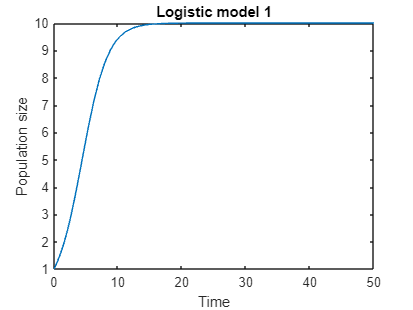

t0 = 0; 
tf = 50; 
N0 = 1; 
r = .5;
[T, vNint] = ode45(@(T, vNint) logGrowth(T,vNint,r,10), [t0 tf], N0); 
[T2, vNint2] = ode45(@(T2, vNint2) logGrowth(T2,vNint2,r,100), [t0 tf], N0);

figure;
plot(T,vNint)  
xlabel('Time'), ylabel('Population size'),title('Logistic model 1')

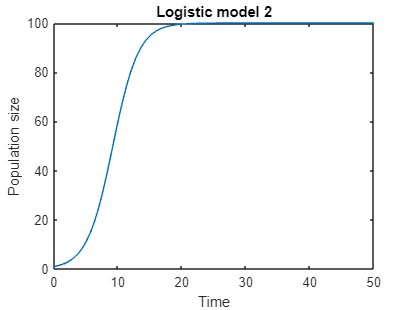

figure;
plot(T2,vNint2)  
xlabel('Time'), ylabel('Population size'),title('Logistic model 2')

In both plots, the populations reach carrying capacity slightly after 10 seconds although logistic model 2 seems to reach it a bit slower. However, logistic model 2 has a much faster rate of population growth compared to logistic model 1 due to the fact that model 2 has a much higher carrying capacity compared to model 1. This is due to the fact that because we kept all of the other parameters the same, the second model has to reach carrying capacity in the same time limit, so its rate of growth must increase in order to do so.

Problem 6

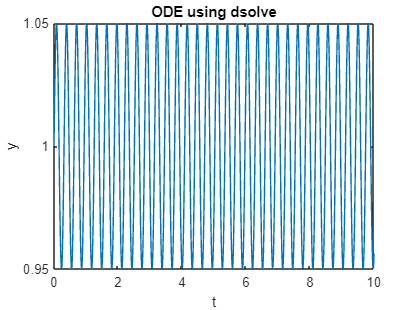

syms y(t)
eqn = diff(y,t) == cos(20*t);
cond = y(0) == 1;
ySol(t) = dsolve(eqn,cond);
ta = 0:.01:10;
plot(ta,ySol(ta))
xlabel('t'), ylabel('y'),title('ODE using dsolve')


t0 = 0;
tend = 10;
y0 = 1;
eq(t) = sin(20*t)/20 + 1

$$eq(t) = \frac{\sin\left(20\,t\right)}{20}+1$$

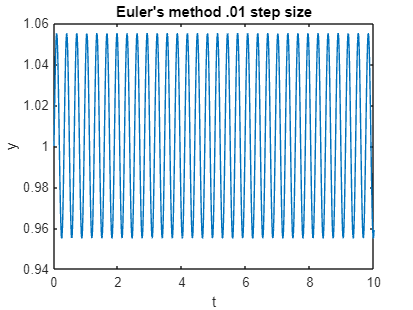


tb = 0:.01:10;
out1 = eul(@ordeq,t0,.01,tend,y0);
figure;
plot(tb, out1)
xlabel('t'), ylabel('y'),title("Euler's method .01 step size")

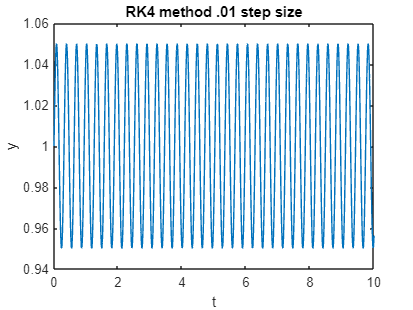

out2 = RK4(@ordeq,t0,.01,tend,y0);
figure;
plot(tb, out2)
xlabel('t'), ylabel('y'),title("RK4 method .01 step size")

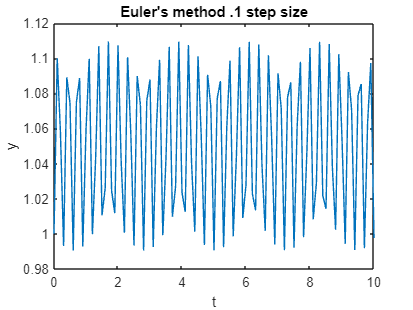


tc = 0:.1:10;
out3 = eul(@ordeq,t0,.1,tend,y0);
figure;
plot(tc, out3)
xlabel('t'), ylabel('y'),title("Euler's method .1 step size")

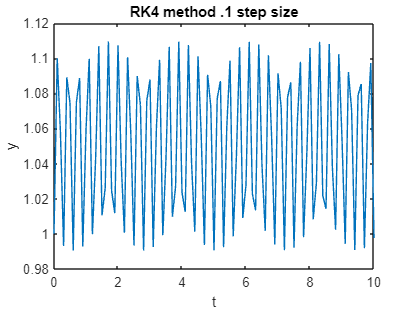

out4 = eul(@ordeq,t0,.1,tend,y0);
figure;
plot(tc, out4)
xlabel('t'), ylabel('y'),title("RK4 method .1 step size")

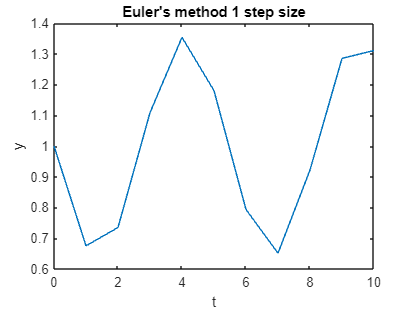


td = 0:1:10;
out5 = RK4(@ordeq,t0,1,tend,y0);
figure;
plot(td, out5)
xlabel('t'), ylabel('y'),title("Euler's method 1 step size")

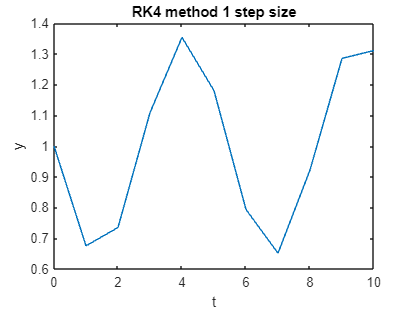

out6 = RK4(@ordeq,t0,1,tend,y0);
figure;
plot(td, out6)
xlabel('t'), ylabel('y'),title("RK4 method 1 step size")

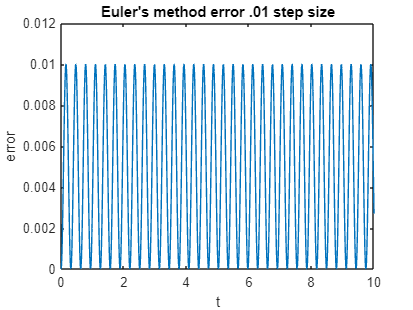


figure;
plot(tb, abs(eq(tb)-out1.'))
xlabel('t'), ylabel('error'),title("Euler's method error .01 step size")

[max1, ind1] = max(abs(eq(tb)-out1.'))

$$max1 = \frac{38669608406645}{4503599627370496}-\frac{\sin\left(\frac{707}{5}\right)}{20}$$

ind1 = 708

disp([max1, ind1])

$$\left(\begin{array}{cc} \frac{38669608406645}{4503599627370496}-\frac{\sin\left(\frac{707}{5}\right)}{20} & 708 \end{array}\right)$$

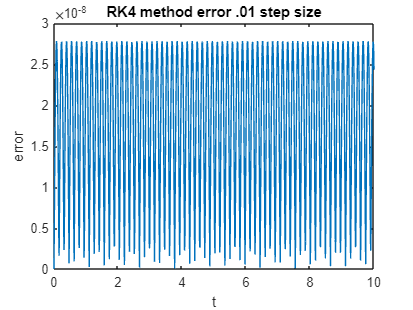


figure;
plot(tb, abs(eq(tb)-out2.'))
xlabel('t'), ylabel('error'),title("RK4 method error .01 step size")

[max2, ind2] = max(abs(eq(tb)-out2.'))

$$max2 = \frac{56295005198199}{1125899906842624}-\frac{\sin\left(\frac{699}{5}\right)}{20}$$

ind2 = 700

disp([max2, ind2])

$$\left(\begin{array}{cc} \frac{56295005198199}{1125899906842624}-\frac{\sin\left(\frac{699}{5}\right)}{20} & 700 \end{array}\right)$$

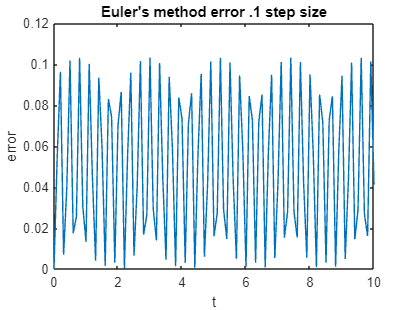


figure;
plot(tc, abs(eq(tc)-out3.'))
xlabel('t'), ylabel('error'),title("Euler's method error .1 step size")

[max3, ind3] = max(abs(eq(tc)-out3.'))

$$max3 = \frac{3032514527373}{35184372088832}-\frac{\sin\left(148\right)}{20}$$

ind3 = 75

disp([max3, ind3])

$$\left(\begin{array}{cc} \frac{3032514527373}{35184372088832}-\frac{\sin\left(148\right)}{20} & 75 \end{array}\right)$$

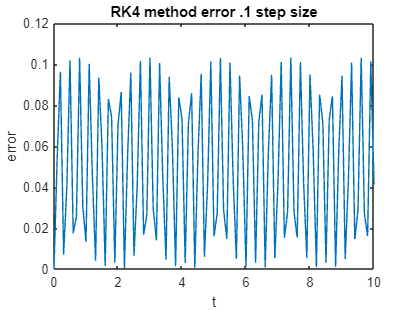


figure;
plot(tc, abs(eq(tc)-out4.'))
xlabel('t'), ylabel('error'),title("RK4 method error .1 step size")

[max4, ind4] = max(abs(eq(tc)-out4.'))

$$max4 = \frac{3032514527373}{35184372088832}-\frac{\sin\left(148\right)}{20}$$

ind4 = 75

disp([max4, ind4])

$$\left(\begin{array}{cc} \frac{3032514527373}{35184372088832}-\frac{\sin\left(148\right)}{20} & 75 \end{array}\right)$$

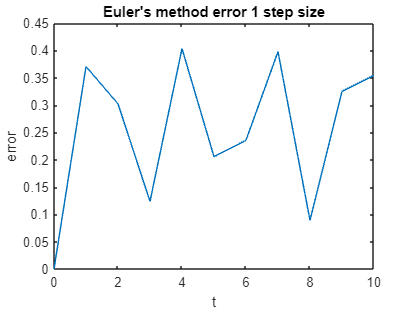


figure;
plot(td, abs(eq(td)-out5.'))
xlabel('t'), ylabel('error'),title("Euler's method error 1 step size")

[max5, ind5] = max(abs(eq(td)-out5.'))

$$max5 = \frac{795986991715459}{2251799813685248}-\frac{\sin\left(80\right)}{20}$$

ind5 = 5

disp([max5, ind5])

$$\left(\begin{array}{cc} \frac{795986991715459}{2251799813685248}-\frac{\sin\left(80\right)}{20} & 5 \end{array}\right)$$

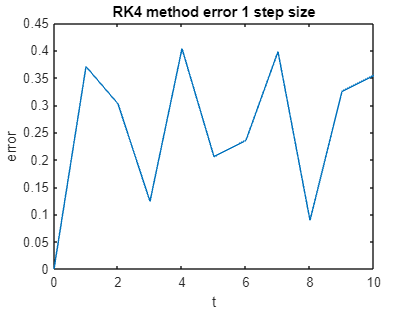


figure;
plot(td, abs(eq(td)-out6.'))
xlabel('t'), ylabel('error'),title("RK4 method error 1 step size")

[max6, ind6] = max(abs(eq(td)-out6.'))

$$max6 = \frac{795986991715459}{2251799813685248}-\frac{\sin\left(80\right)}{20}$$

ind6 = 5

disp([max6, ind6])

$$\left(\begin{array}{cc} \frac{795986991715459}{2251799813685248}-\frac{\sin\left(80\right)}{20} & 5 \end{array}\right)$$

As the step size increases, the margin of error increases, which is evident for both RK4 and Euler's methods. As seen with the step 1 size, the largest margin of error goes up to roughly .4, while for the smallest step size (.01), the margin of error is to 10^-8 power. This follows the trend that as step size gets smaller, the more accurate the graph is.

Problem 2 (continued)

function N = factorial_recur(n)
if n == 1
N = 1;
else
N = n*factorial_recur(n-1);
end
end

Problem 5 (continued)

function dNdt = logGrowth(t,N,r,K)
dNdt = r*N.*(1-N/K);
end

Problem 6 (continued)

function dydt = ordeq(t,y)
dydt = cos(20*t);
end